## **AERO95002 Numerical Analysis 2019-2020**

## **Coursework 1**

## **Dr. Elnaz Naghibi**

## **Due Date: 17 February 2020**

### **Question 1 [15%]**

Plot the function $f\left(x\right)=\cos \;x\;\left(e^{2x} -2e^x +1\right)$ in the interval $\left\lbrack -\pi /4,3\pi /4\right\rbrack$ and find its roots using MATLAB functions.

Explore the four methods of root finding discussed in the lecture notes and select an efficient method to find each root. Discuss your rationale and provide the code presenting the most efficient method for each root. Show the convergence to each root using appropriate plots. Finally, compare the number of iterations required to obtain each root and discuss the reason behind the difference in convergence rates of the two roots.

**Answer:**

You can use this space to explain the answers and include equations as needed using either Latex code or the live script equation editor from the tab "insert".

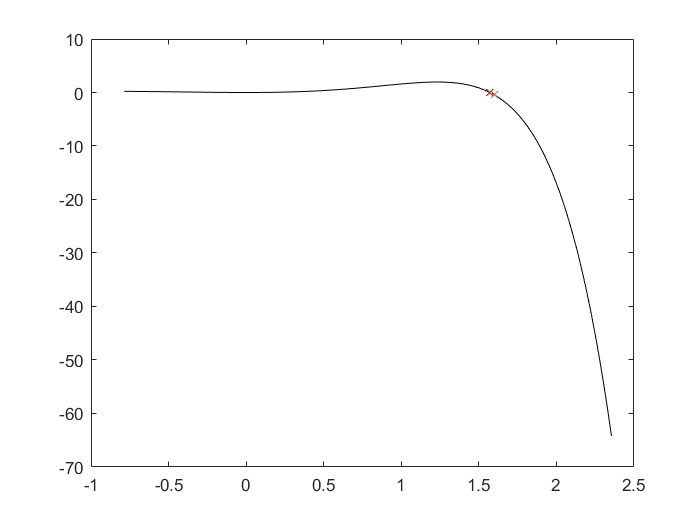

% Use this box for coding. 
% Outputs and graphs will be displayed on the right panel.
% To avoid submitting multiple files, please include functions at the bottom of your scripts.
%%coded by Jiaxuan Tang; CID:01486551;
%Question1;


clear
clc

x = -pi/4:0.01:pi*3/4;
%plot the diagram
%use newton method
plot(x,fx(x),'-k');
hold on;
x0 = 1.6;
tolerance = 0.00001;
while abs(fx(x0)) > tolerance
    plot(x0,fx(x0),'x');
    x1 = x0 - fx(x0)/fbarX(x0);
    x0 = x1;
    hold on
end

hold off;


fprintf('The root of this function is %4.3f.',x0);

The root of this function is 1.571.

### **Question 2 [30%]**

**Part a:  [15 %]**

Calculate Legendre polynomial of degree 5 using equation 16 in Handout_4 and MATLAB symbolic toolbox. Compare your resulting polynomial with "legendreP" function in MATLAB. Plot this function in the interval $\left\lbrack -1\ldotp 1\right\rbrack$ and calculate its roots $\eta_i$. Calculate weighting coefficients $w_i$ using the definition in equation 21. Using  $\eta_i$ and $w_i$, calculate the integral of $\int_{-1}^2 \left({\textrm{ax}}^9 +{\textrm{bx}}^4 +\textrm{cx}\right)\;\textrm{dx}$ and show that it will be the same as its analytical value.

**Answer:**

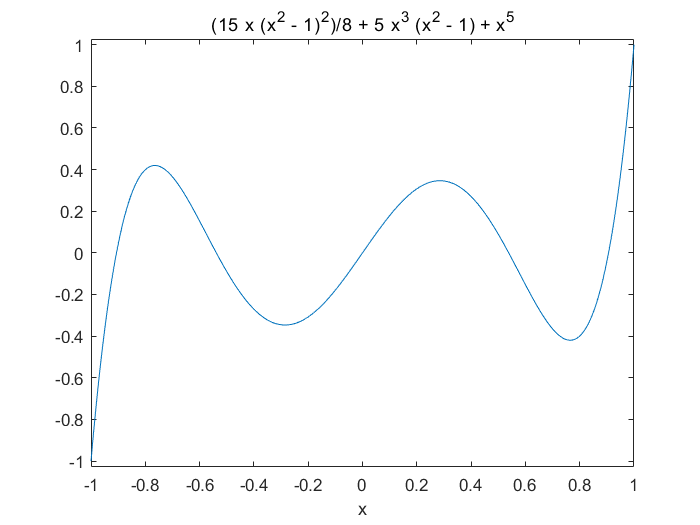

%%Question 2a

clear
clc

N=5;
syms x;
Ln=1./(2.^N.*factorial(N)).*diff((x.^2-1).^N,N);
%plot the graph of Ln over x
ezplot(Ln,[-1,1]);

LnM = legendreP(5,x);
%x = -1:0.01:1;

x0=solve(Ln,x);
%get roots

ni=[];
for i =1:length(x0)
    if x0(i)>=-1 && x0(i)<=2
        ni = [ni,x0(i)];
    end
end
%ni calculated

wi = 2./(1-(ni).^2)*(diff(Ln,1)).^(-2);
valWi=[];
for i=1:5
    valWi(i) = subs(wi(i),x,ni(i));
end

%wi calculated;
disp(valWi);

    0.5689    0.4786    0.2369    0.4786    0.2369



disp(ni);

$$\left(\begin{array}{ccccc} 0 & -\sqrt{\frac{5}{9}-\frac{2\,\sqrt{2}\,\sqrt{35}}{63}} & -\sqrt{\frac{2\,\sqrt{2}\,\sqrt{35}}{63}+\frac{5}{9}} & \sqrt{\frac{5}{9}-\frac{2\,\sqrt{2}\,\sqrt{35}}{63}} & \sqrt{\frac{2\,\sqrt{2}\,\sqrt{35}}{63}+\frac{5}{9}} \end{array}\right)$$

%calculate the integration

dy = wi*fx2B(ni).';
disp(dy);

$$\begin{array}{l} \frac{2\,\left(\sigma_{3}+\sigma_{5}+\sigma_{7}\right)}{\sigma_{2}}-\frac{2\,\left(\sigma_{4}+\sigma_{6}+\sigma_{8}\right)}{\sigma_{1}}+\frac{2\,\left(\sigma_{4}-\sigma_{6}+\sigma_{8}\right)}{\sigma_{1}}-\frac{2\,\left(\sigma_{3}-\sigma_{5}+\sigma_{7}\right)}{\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}=\left(\sigma_{10}-\frac{4}{9}\right)\,\sigma_{9}\\ \sigma_{2}=\left(\sigma_{10}+\frac{4}{9}\right)\,\sigma_{9}\\ \sigma_{3}=a\,{\left(\frac{5}{9}-\sigma_{10}\right)}^{9/2}\\ \sigma_{4}=a\,{\left(\sigma_{10}+\frac{5}{9}\right)}^{9/2}\\ \sigma_{5}=b\,{\left(\sigma_{10}-\frac{5}{9}\right)}^{2}\\ \sigma_{6}=b\,{\left(\sigma_{10}+\frac{5}{9}\right)}^{2}\\ \sigma_{7}=c\,\sqrt{\frac{5}{9}-\sigma_{10}}\\ \sigma_{8}=c\,\sqrt{\sigma_{10}+\frac{5}{9}}\\ \sigma_{9}={\left(\frac{45\,x^{2}\,\left(x^{2}-1\right)}{2}+\frac{15\,{\left(x^{2}-1\right)}^{2}}{8}+15\,x^{4}\right)}^{2}\\ \sigma_{10}=\frac{2\,\sqrt{2}\,\sqrt{35}}{63} \end{array}$$

**Part b: [15 %]**

Use mid-point, trapezium and Simpson integration schemes to calculate the below integrals for $n=25,50,100,200$ and provide the code for each method accordingly.


$$\int_0^{3\pi } \mathrm{sinx}\;\mathrm{dx}$$



$$\int_0^{3\pi } \left|\mathrm{sinx}\right|\;\mathrm{dx}$$



$$\int_0^{3\pi } {\mathrm{sin}}^2 x\;\mathrm{dx}$$


Calculate the errors for every value of $n$ using analytical values of integration and list the order of accuracy of the schemes as you double $n$ in each round. Compare your calculated orders of accuracy with theoretical values in chapter 3.2 of the text book "‘Fundamentals of Engineering Numerical Analysis". Discuss how different choices of integrand functions can affect the order of accuracy in the numerical schemes. 

**Answer:**

%%question 2b
clear
clc

%change n in each iteration
n=[25,50,100,200];

%initialize the integral
IntSinMid = zeros(4,1);
IntAbsSinMid = zeros(4,1);
IntSin2Mid = zeros(4,1);

IntAbsSinTrapz = zeros(4,1);
IntSinTrapz = zeros(4,1);
IntSin2Trapz = zeros(4,1);

IntSinSim = zeros(4,1);
IntAbsSinSim = zeros(4,1);
IntSin2Sim = zeros(4,1);


%mid-point rule;
for num = 1:4
    h1(num) = 3*pi/n(num);

    for i = 0:n(num)-1
        xmi(num) = 0 + h1(num)*((2*i + 1)/2);
    
        IntSinMid(num) = IntSinMid(num) + h1(num)*sin(xmi(num));
        IntAbsSinMid(num) = IntAbsSinMid(num) + h1(num)*abs(sin(xmi(num)));
        IntSin2Mid(num) = IntSin2Mid(num) + h1(num)*sin(xmi(num))^2;
    
    end

    %Trapezium rule
    xi=zeros(4,1);

    for i = 1:n(num)
        xi(num, i+1) = 0 + i*h1(num);
    end

    for i = 1:n(num)
        IntSinTrapz(num) = IntSinTrapz(num) + h1(num)*((sin(xi(num,i)) + sin(xi(num,i+1)))/2);
        IntAbsSinTrapz(num) = IntAbsSinTrapz(num) + h1(num)*((abs(sin(xi(num,i))) + abs(sin(xi(num,i+1))))/2);
        IntSin2Trapz(num) = IntSin2Trapz(num) + h1(num)*((sin(xi(num,i))^2 + sin(xi(num,i+1))^2)/2);
    end

    %simpson rule
    for i = 0:n(num)
        if mod(i,2) == 0
            if (i==0) || (i==n(num))
                IntSinSim(num) = IntSinSim(num) + sin(xi(num,i+1));
                IntAbsSinSim(num) = IntAbsSinSim(num) + abs(sin(xi(num,i+1)));
                IntSin2Sim(num) = IntSin2Sim(num) + sin(xi(num,i+1))^2;
            else
                IntSinSim(num) = IntSinSim(num) + 2*sin(xi(num,i+1));
                IntAbsSinSim(num) = IntAbsSinSim(num) + 2*abs(sin(xi(num,i+1)));
                IntSin2Sim(num) = IntSin2Sim(num) + 2*sin(xi(num,i+1))^2;
            end
    
        else
            IntSinSim(num) = IntSinSim(num) + 4*sin(xi(num,i+1));
            IntAbsSinSim(num) = IntAbsSinSim(num) + 4*abs(sin(xi(num,i+1)));
            IntSin2Sim(num) = IntSin2Sim(num) + 4*sin(xi(num,i+1))^2;
        end
    end
    IntSinSim(num) = h1(num)/3*IntSinSim(num);
    IntAbsSinSim(num) = h1(num)/3*IntAbsSinSim(num);
    IntSin2Sim(num) = h1(num)/3*IntSin2Sim(num);

end

enum = 4;
fun1 = @(x) sin(x);
IntAnalyticalSin = integral(fun1,0,3*pi);

fun2 = @(x) abs(sin(x));
IntAnalyticalAbsSin = integral(fun2,0,3*pi);

fun3 = @(x) sin(x).^2;
IntAnalyticalSin2 = integral(fun3,0,3*pi);

errorFun1Mid25 = IntSinMid(1) - IntAnalyticalSin;
errorFun1Sim25 = IntSinSim(1) - IntAnalyticalSin;
errorFun1Trapz25 = IntSinTrapz(1) - IntAnalyticalSin;

errorFun2Mid25 = IntAbsSinMid(1) - IntAnalyticalAbsSin;
errorFun2Sim25 = IntAbsSinSim(1) - IntAnalyticalAbsSin;
erorFun2Trapz25 = IntAbsSinTrapz(1) - IntAnalyticalAbsSin;

errorFun3Mid25 = IntSin2Mid(1) - IntAnalyticalSin2;
errorFun3Sim25 = IntSin2Sim(1) - IntAnalyticalSin2;
errorFun1Trapz25 = IntSin2Trapz(1) - IntAnalyticalSin2;


errorFun1Mid50 = IntSinMid(2) - IntAnalyticalSin;
errorFun1Sim50 = IntSinSim(2) - IntAnalyticalSin;
errorFun1Trapz50 = IntSinTrapz(2) - IntAnalyticalSin;

errorFun2Mid50 = IntAbsSinMid(2) - IntAnalyticalAbsSin;
errorFun2Sim50 = IntAbsSinSim(2) - IntAnalyticalAbsSin;
erorFun2Trapz50 = IntAbsSinTrapz(2) - IntAnalyticalAbsSin;

errorFun3Mid50 = IntSin2Mid(2) - IntAnalyticalSin2;
errorFun3Sim50 = IntSin2Sim(2) - IntAnalyticalSin2;
errorFun1Trapz50 = IntSin2Trapz(2) - IntAnalyticalSin2;


errorFun1Mid100 = IntSinMid(3) - IntAnalyticalSin;
errorFun1Sim100 = IntSinSim(3) - IntAnalyticalSin;
errorFun1Trapz100 = IntSinTrapz(3) - IntAnalyticalSin;

errorFun2Mid100 = IntAbsSinMid(3) - IntAnalyticalAbsSin;
errorFun2Sim100 = IntAbsSinSim(3) - IntAnalyticalAbsSin;
erorFun2Trapz100 = IntAbsSinTrapz(3) - IntAnalyticalAbsSin;

errorFun3Mid100 = IntSin2Mid(3) - IntAnalyticalSin2;
errorFun3Sim100 = IntSin2Sim(3) - IntAnalyticalSin2;
errorFun1Trapz100 = IntSin2Trapz(3) - IntAnalyticalSin2;


errorFun1Mid200 = IntSinMid(4) - IntAnalyticalSin;
errorFun1Sim200 = IntSinSim(4) - IntAnalyticalSin;
errorFun1Trapz200 = IntSinTrapz(4) - IntAnalyticalSin;

errorFun2Mid200 = IntAbsSinMid(4) - IntAnalyticalAbsSin;
errorFun2Sim200 = IntAbsSinSim(4) - IntAnalyticalAbsSin;
erorFun2Trapz200 = IntAbsSinTrapz(4) - IntAnalyticalAbsSin;

errorFun3Mid200 = IntSin2Mid(4) - IntAnalyticalSin2;
errorFun3Sim200 = IntSin2Sim(4) - IntAnalyticalSin2;
errorFun1Trapz200 = IntSin2Trapz(4) - IntAnalyticalSin2;

fprintf('The intergral of sinx using mid-point rule is %3.3f',IntSinMid(enum));

The intergral of sinx using mid-point rule is 2.000

fprintf('The intergral of abs sinx using mid-point rule is %3.3f',IntAbsSinMid(enum));

The intergral of abs sinx using mid-point rule is 6.000

fprintf('The intergral of sinx^2 using mid-point rule is %3.3f',IntSin2Mid(enum));

The intergral of sinx^2 using mid-point rule is 4.712


fprintf('The integral of sinx using tapz is %3.3f',IntSinTrapz(enum));

The integral of sinx using tapz is 2.000

fprintf('The integral of abs sinx using tapz is %3.3f',IntAbsSinTrapz(enum));

The integral of abs sinx using tapz is 6.000

fprintf('The integral of sinx ^ 2 using tapz is %3.3f',IntSin2Trapz(enum));

The integral of sinx ^ 2 using tapz is 4.712


fprintf('The integral of sinx using simpson is %3.3f',IntSinSim(enum));

The integral of sinx using simpson is 2.000

fprintf('The integral of abs sinx using simpson is %3.3f',IntAbsSinSim(enum));

The integral of abs sinx using simpson is 6.000

fprintf('The integral of sinx ^ 2 using simpson is %3.3f',IntSin2Sim(enum));

The integral of sinx ^ 2 using simpson is 4.712

### **Question 3 [25%]**

Use Chebyshev distribution to sample 5 values of function $f\left(x\right)=\frac{1}{\cosh \;x}$ in the interval $\left\lbrack -2,2\right\rbrack$. Write a code to calculate the cubic spline passing though these points. Increase the number of points to 15 and rebuild the cubic spline. Compare your results with equally-spaced arrays of function values for n=5 and n=15 and report the Euclidean norm of error in each case.

**Answer:**

clear
clc



### **Question 4 [30%]**

**Part a: [15 %]**

Using the MATLAB command "meshgrid", create a $100\;\times \;100$ grid on the interval $x,y$$\in \left\lbrack -1,1\right\rbrack$. Create the discretized values of the function $f\left(x,y\right)=x^3 +3{\textrm{yx}}^2$ in this interval. Calculate 2D distributions of $\frac{\partial f}{\partial x}$ and  $\frac{\partial f}{\partial y}$ using finite difference schemes (use central difference for interior points and forward/backward difference for the points on the boundary). Plot the numerically calculated profiles of  $\frac{\partial f}{\partial x}$ and  $\frac{\partial f}{\partial y}$ on planes$x=0$ and $y=0\ldotp 5$and compare them with the analytical profiles of the derivatives.

**Answer:**

**Part b: [15 %]**

Use the systematic method to construct the finite-difference approximation of  $\frac{{\mathrm{d}}^4 f}{\mathrm{d}x^4 }$ using the stencil $\left(-2,-1,0,1,2\right)$. Report the coefficients obtained and the order of the truncation error in this approximation. Comment under which circumstance this approximation will provide an exact solution.

**Answer:**

function y = fx(x)
 y = cos(x).*(exp(2.*x) - 2.*exp(x) + 1);
end

function dydx = fbarX(x)
 dydx = -sin(x) .*(exp(2.*x) - 2.*exp(x) + 1) + cos(x) .*(2.*exp(2.*x) - 2.*exp(x));  
end

function y = fx2B(x)
syms a b c
 y=a.*x.^9+b.*x.^4+c.*x;
end
